# PROVA FINALE

## Orbits characterization

#### Starting orbit

We are given the data in the ECI coordinates system as radius and velocity of the starting point:

R_i = [-1788.3462 -9922.9190 -1645.8335];
V_i = [5.6510 -1.1520 -1.8710];

To characterize the orbit we need to find the orbital elements

mu = 398600;
[a_i, e_i, i_i, OM_i, w_i, theta_i] = rv2parorb(R_i, V_i, mu)

a_i = 9.6581e+03

e_i = 0.0915

i_i = 0.3455

OM_i = 0.9218

w_i = 1.3142

theta_i = 2.3232

#### Final orbit

This time we are given the data as orbital elements:

a_f = 13290.0000;
e_f = 0.3855;
i_f = 0.9526;
OM_f = 2.5510;
w_f = 2.2540;
theta_f = 3.0360;

To get the ending point we need to calculate its radius and its velocity

[R_f, V_f] = parorb2rv(a_f, e_f, i_f, OM_f, w_f, theta_f, mu)

R_f = 1.0e+04 *

   -0.3361    1.2979   -1.2527


V_f =    -3.2360    0.9160    1.4639


#### Orbits plot

We can now plot the two orbit, with their respective starting and final points:

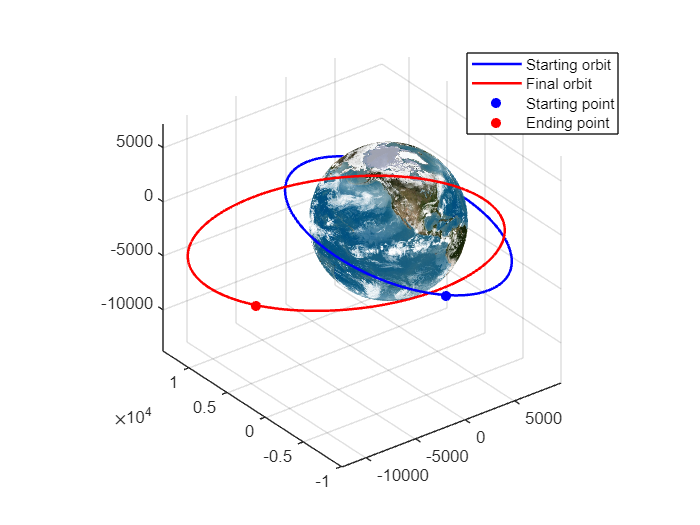

figure();
plotOrbit(a_i, e_i, i_i, OM_i, w_i, 0, 2*pi, 0.01, mu, 'b');
hold on; axis equal;
plotOrbit(a_f, e_f, i_f, OM_f, w_f, 0, 2*pi, 0.01, mu, 'r');
scatter3(R_i(1), R_i(2), R_i(3), 'blue', 'filled');
scatter3(R_f(1), R_f(2), R_f(3), 'red', 'filled');
earthPlot;
legend("Starting orbit", "Final orbit", "Starting point", "Ending point", ...
        'Location', 'best');

## Standard transfer

#### Plane change

We start by changing the plane so that our trasfer orbit is coplanar with the final orbit.

The transfer orbit obtained will have the following orbital elements:

a_plch = a_i;
e_plch = e_i;
i_plch = i_f;
OM_plch = OM_f;

Note: the pericenter anomaly has to be calculated, it can't be decide from the start.

Now we need to identify what angle variation we'll have to consider, as this is needed to identify the spherical triangle we'll need to solve:

delta_OM = OM_plch - OM_i

delta_OM = 1.6292

delta_i = i_plch - i_i

delta_i = 0.6071

As both of them are positive, we'll consider the following spherical triangle:

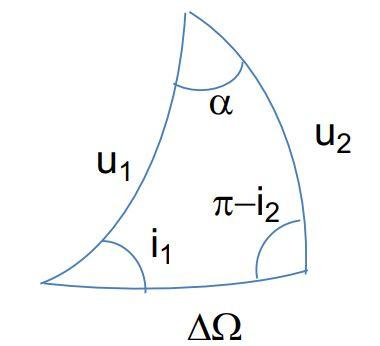(Note: i1 = i_i, i2 = i_plch)

alpha = acos(-cos(i_i)*cos(pi-i_plch) + sin(i_i)*sin(pi-i_plch)*cos(delta_OM));
cos_u1 = (cos(pi-i_plch) + cos(i_i)*cos(alpha))/(sin(i_i)*sin(alpha));
cos_u2 = (cos(i_i) + cos(pi-i_plch)*cos(alpha))/(sin(pi-i_plch)*sin(alpha));
sin_u1 = sin(delta_OM)/sin(alpha)*sin(pi-i_plch);
sin_u2 = sin(delta_OM)/sin(alpha)*sin(i_i);
u_1 = atan2(sin_u1, cos_u1);
u_2 = atan2(sin_u2, cos_u2);
theta_plch = u_1 - w_i

theta_plch = 0.5447

if (u_2 - theta_plch) < 0
    w_plch = 2*pi + (u_2 - theta_plch)
else
    w_plch = u_2 - theta_plch;
end

w_plch = 6.1483

As we want the maneuver to have the lowest velocity variation we use the farthest point from earth, so the true anomaly becomes:

theta_plch = theta_plch + pi

theta_plch = 3.6863

We can now plot the two orbits with the point where the maneuver will be executed:

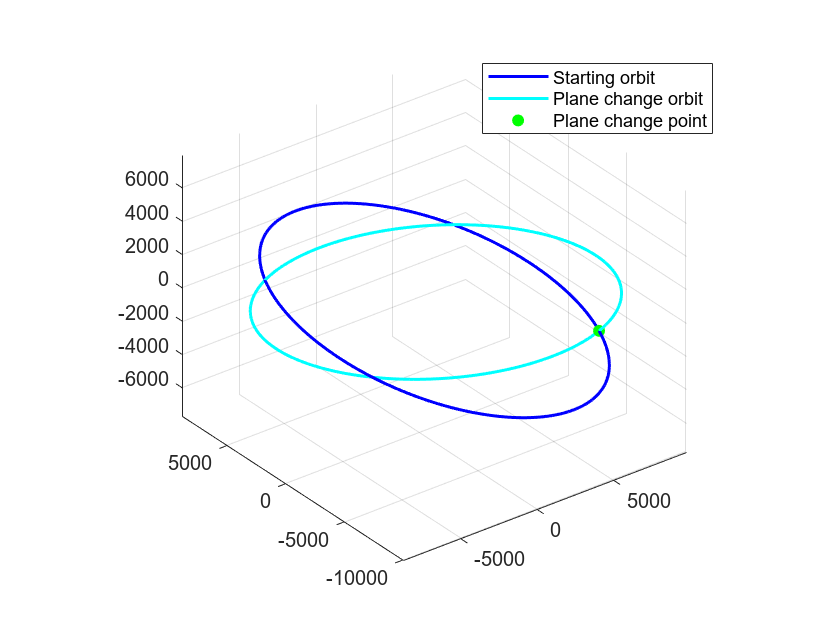

figure();
[R_plch,~] = parorb2rv(a_plch, e_plch, i_plch, OM_plch, w_plch, theta_plch, mu);
plotOrbit(a_i, e_i, i_i, OM_i, w_i, 0, 2*pi, 0.01, mu, 'b');
hold on; axis equal; grid on;
plotOrbit(a_plch, e_plch, i_plch, OM_plch, w_plch, 0, 2*pi, 0.01, mu, 'c');
scatter3(R_plch(1), R_plch(2), R_plch(3), 'green', 'filled');
earthPlot;
legend("Starting orbit", "Plane change orbit", "Plane change point", ...
        'Location', 'best');

The velocity variation needed we'll be:

p_plch = a_plch*(1-e_plch^2);
delta_v_plch = 2*sqrt(mu/p_plch)*(1+e_plch*cos(theta_plch))*sin(alpha/2)

delta_v_plch = 5.7700

The time needed to reach the maneuver point from the starting point is:

dt_i_plch = CalcoloTempi(a_i, e_i, mu, theta_i, theta_plch) % [sec]

dt_i_plch = 6.8482e+03

dt_i_plch/60 % [min]

ans = 114.1374

#### Pericenter anomaly change

If we plot the transfer orbit we just obtained and the final orbit, we can see that their apsidal axis are not aligned, thus we'll need to do a maneuver to change the transfer pericenter anomaly:

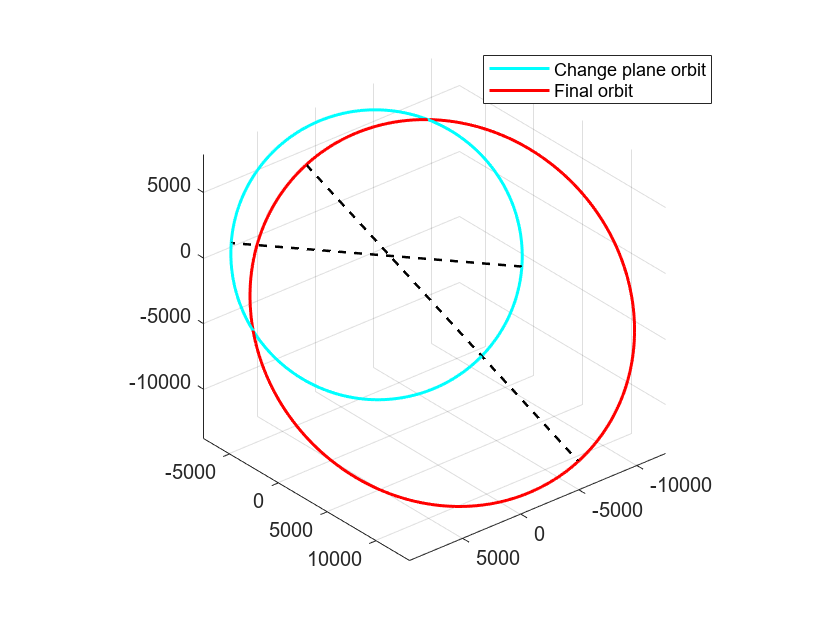

figure();
plotOrbit(a_plch, e_plch, i_plch, OM_plch, w_plch, 0, 2*pi, 0.01, mu, 'c');
hold on; axis equal; grid on;
plotOrbit(a_f, e_f, i_f, OM_f, w_f, 0, 2*pi, 0.01, mu, 'r');
plotApsidalAxis(a_plch, e_plch, i_plch, OM_plch, w_plch, mu);
plotApsidalAxis(a_f, e_f, i_f, OM_f, w_f, mu);
view(140, 30)
legend("Change plane orbit", "Final orbit", 'Location','best');

delta_w = w_f - w_plch;
if delta_w < 0
    delta_w = delta_w + 2*pi
end

delta_w = 2.3889

The new trasfer orbit can be characterized:

a_anch = a_plch;
e_anch = e_plch;
i_anch = i_plch;
OM_anch = OM_plch;
w_anch = w_f

w_anch = 2.2540

theta_anch = 2*pi - (delta_w/2)

theta_anch = 5.0888

If we plot the old and the new transfer orbit we'll see how the apsidal axis is rotated and the point were the maneuver was executed:

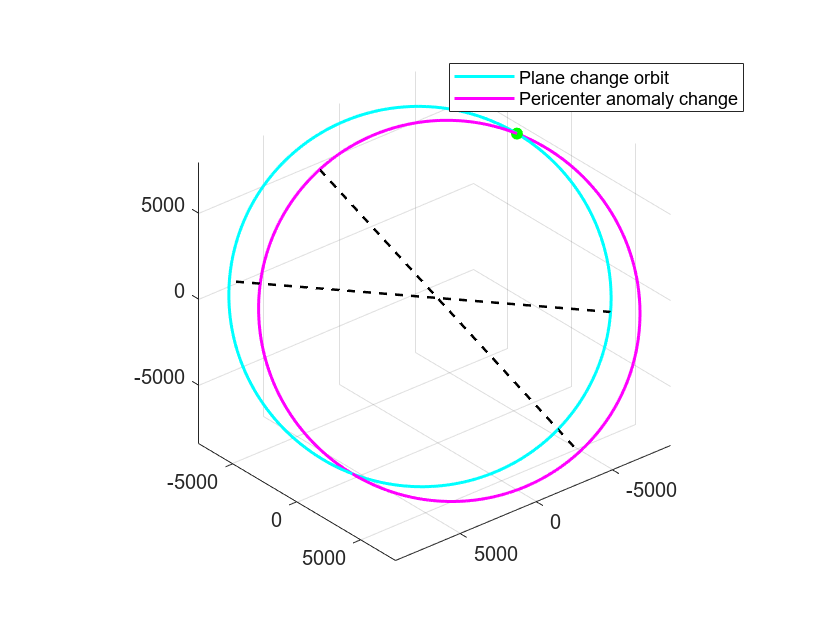

figure();
[R_anch, ~] = parorb2rv(a_anch, e_anch, i_anch, OM_anch, w_anch, theta_anch, mu);
plotOrbit(a_plch, e_plch, i_plch, OM_plch, w_plch, 0, 2*pi, 0.01, mu, 'c');
hold on; axis equal; grid on;
plotOrbit(a_anch, e_anch, i_anch, OM_anch, w_anch, 0, 2*pi, 0.01, mu, 'm');
plotApsidalAxis(a_plch, e_plch, i_plch, OM_plch, w_plch, mu);
plotApsidalAxis(a_anch, e_anch, i_anch, OM_anch, w_anch, mu);
scatter3(R_anch(1), R_anch(2), R_anch(3), 'green', 'filled');
view(140, 30)
legend("Plane change orbit", "Pericenter anomaly change", 'Location','northeast');

The velocity variation required is:

delta_v_anch = 2*sqrt(mu/(a_anch*(1-e_anch^2)))*e_anch*sin(theta_anch)

delta_v_anch = -1.0984

The time needed to reach the maneuver point from the last transfer point is:

dt_plch_anch = CalcoloTempi(a_plch, e_plch, mu, theta_plch, theta_anch) % [sec]

dt_plch_anch = 2.2064e+03

dt_plch_anch/60 % [min]

ans = 36.7738

#### Change orbit form

Now we just need to change the orbit form to get to the final orbit.

We have various ways to do this: bitangent either starting from apogee or perigee, secant or bielliptic.

We'll start analizing the bitangent maneuver starting from transfer orbit's apogee, reaching final orbit's perigee:

[R_a_anch, V_a_anch] = parorb2rv(a_anch, e_anch, i_anch, OM_anch, w_anch, pi, mu);
[R_p_f, V_p_f] = parorb2rv(a_f, e_f, i_f, OM_f, w_f, 0, mu);
r_a_tras = norm(R_a_anch)

r_a_tras = 1.0542e+04

r_p_tras = norm(R_p_f)

r_p_tras = 8.1667e+03

a_tras = (r_a_tras + r_p_tras)/2

a_tras = 9.3544e+03

e_tras = (r_a_tras - r_p_tras)/(r_a_tras + r_p_tras)

e_tras = 0.1270

i_tras = i_f;
OM_tras = OM_f;
w_tras = w_f;

If we plot the orbits we can see the path generated by the bitangent maneuver:

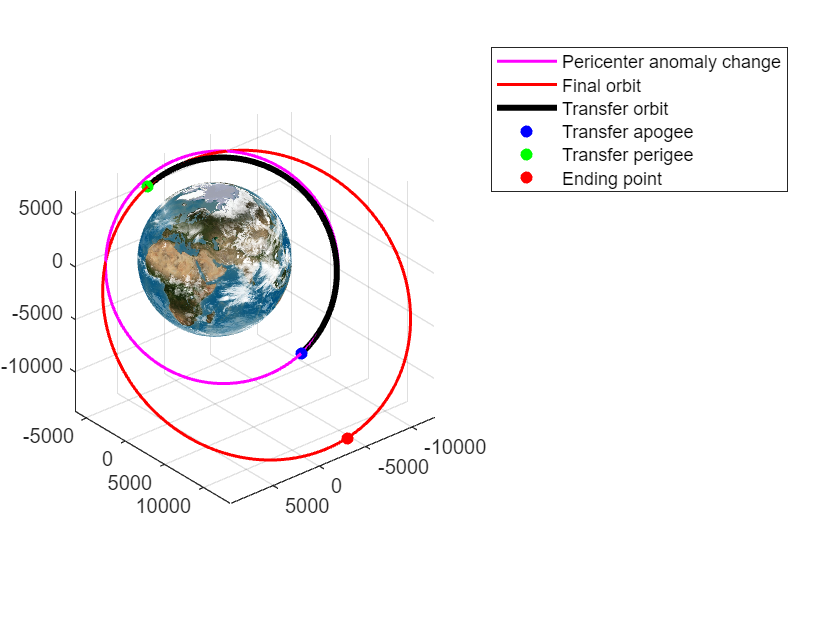

figure();
plotOrbit(a_anch, e_anch, i_anch, OM_anch, w_anch, 0, 2*pi, 0.01, mu, 'm');
hold on; axis equal; grid on;
plotOrbit(a_f, e_f, i_f, OM_f, w_f, 0, 2*pi, 0.01, mu, 'r');
p = plotOrbit(a_tras, e_tras, i_tras, OM_tras, w_tras, pi, 2*pi, 0.01, mu, 'k');
set(p, 'LineWidth', 3);
scatter3(R_a_anch(1), R_a_anch(2), R_a_anch(3), 'blue', 'filled');
scatter3(R_p_f(1), R_p_f(2), R_p_f(3), 'green', 'filled');
scatter3(R_f(1), R_f(2), R_f(3), 'red', 'filled');
earthPlot;
view(140, 30);
legend("Pericenter anomaly change", "Final orbit", "Transfer orbit", ...
    "Transfer apogee", "Transfer perigee" , "Ending point", 'Location', 'northeastoutside');

In this case, the necessary velocity variation will be:

v_a_anch = norm(V_a_anch);
v_a_tras = sqrt(mu/(a_tras*(1-e_tras^2)))*(1-e_tras);
v_p_tras = sqrt(mu/(a_tras*(1-e_tras^2)))*(1+e_tras);
v_p_f = norm(V_p_f);
dv_apo = v_a_tras - v_a_anch

dv_apo = -0.1154

dv_peri = v_p_f - v_p_tras

dv_peri = 0.8068

dv_tot_ap = abs(dv_apo) + abs(dv_peri)

dv_tot_ap = 0.9222

The time needed to reach the final point is the sum of the time needed to reach the transfer orbit's apogee on the Pericenter anomaly change orbit, the time spent on the transfer orbit to reach the final one and the time needed to move from transfer's perigee to the final point:

dt_anch_tras = CalcoloTempi(a_anch, e_anch, mu, theta_anch, pi) % [sec]

dt_anch_tras = 6.2693e+03

dt_ap_tras = CalcoloTempi(a_tras, e_tras, mu, pi, 0) % [sec]

dt_ap_tras = 4.5020e+03

dt_tras_f = CalcoloTempi(a_f, e_f, mu, 0, theta_f) % [sec]

dt_tras_f = 7.0919e+03

dt_anch_f = dt_anch_tras + dt_ap_tras + dt_tras_f % [sec]

dt_anch_f = 1.7863e+04

dt_anch_f/60^2 % [hr]

ans = 4.9620

The total time for the entire transfer is:

dt_tot_ap = dt_i_plch + dt_plch_anch + dt_anch_f % [sec]

dt_tot_ap = 2.6918e+04

dt_tot_ap/(60^2) % [hr]

ans = 7.4772

While still using a bitangent maneuver, we can choose to start from the transfer orbit's perigee, to reach the final orbit's apogee:

[R_p_anch, V_p_anch] = parorb2rv(a_anch, e_anch, i_anch, OM_anch, w_anch, 0, mu);
[R_a_f, V_a_f] = parorb2rv(a_f, e_f, i_f, OM_f, w_f, pi, mu);
r_p_tras = norm(R_p_anch)

r_p_tras = 8.7740e+03

r_a_tras = norm(R_a_f)

r_a_tras = 1.8413e+04

a_tras = (r_a_tras + r_p_tras)/2

a_tras = 1.3594e+04

e_tras = (r_a_tras - r_p_tras)/(r_a_tras + r_p_tras)

e_tras = 0.3546

i_tras = i_f;
OM_tras = OM_f;
w_tras = w_f;

If we plot the orbits we can see the path generated by the bitangent maneuver:

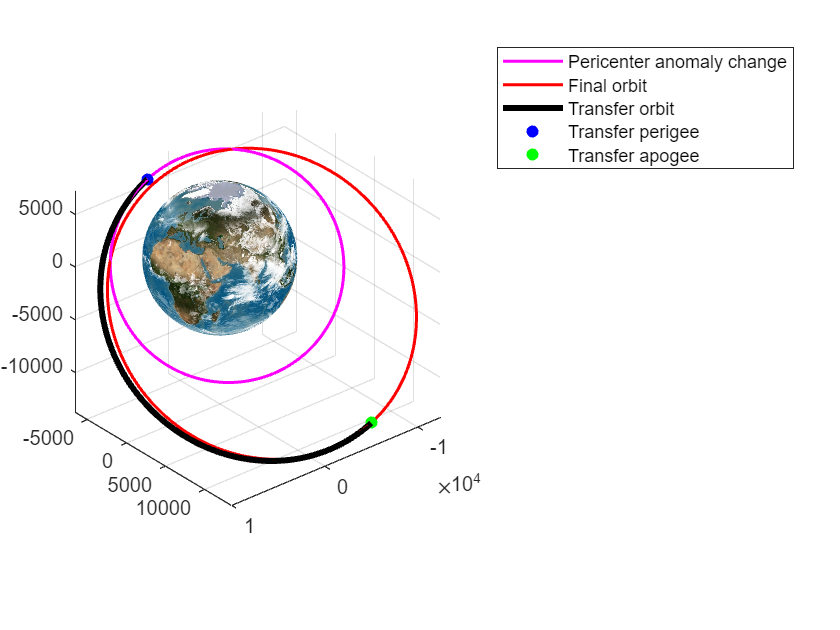

figure();
plotOrbit(a_anch, e_anch, i_anch, OM_anch, w_anch, 0, 2*pi, 0.01, mu, 'm');
hold on; axis equal; grid on;
plotOrbit(a_f, e_f, i_f, OM_f, w_f, 0, 2*pi, 0.01, mu, 'r');
p = plotOrbit(a_tras, e_tras, i_tras, OM_tras, w_tras, 0, pi, 0.01, mu, 'k');
set(p, 'LineWidth', 3);
scatter3(R_p_anch(1), R_p_anch(2), R_p_anch(3), 'blue', 'filled');
scatter3(R_a_f(1), R_a_f(2), R_a_f(3), 'green', 'filled');
view(140, 30);
earthPlot;
legend("Pericenter anomaly change", "Final orbit", "Transfer orbit", ...
    "Transfer perigee", "Transfer apogee", 'Location', 'northeastoutside');

In this case, the necessary velocity variation will be:

v_p_anch = norm(V_p_anch);
v_p_tras = sqrt(mu/(a_tras*(1-e_tras^2)))*(1+e_tras);
v_a_tras = sqrt(mu/(a_tras*(1-e_tras^2)))*(1-e_tras);
v_a_f = norm(V_a_f);
dv_peri = v_p_tras - v_p_anch

dv_peri = 0.8027

dv_apo = v_a_f - v_a_tras

dv_apo = -0.0907

dv_tot_pa = abs(dv_peri) + abs(dv_apo)

dv_tot_pa = 0.8934

As for the previous case, we can calculate the total time as the sum of the ones needed to reach every maneuver's point:

dt_anch_tras = CalcoloTempi(a_anch, e_anch, mu, theta_anch, 0) % [sec]

dt_anch_tras = 1.5463e+03

dt_ap_tras = CalcoloTempi(a_tras, e_tras, mu, 0, pi) % [sec]

dt_ap_tras = 7.8865e+03

dt_tras_f = CalcoloTempi(a_f, e_f, mu, pi, theta_f) % [sec]

dt_tras_f = 1.4716e+04

dt_anch_f = dt_anch_tras + dt_ap_tras + dt_tras_f % [sec]

dt_anch_f = 2.4148e+04

dt_anch_f/60^2 % [hr]

ans = 6.7079

The total time for the entire transfer is:

dt_tot_pa = dt_i_plch + dt_plch_anch + dt_anch_f % [sec]

dt_tot_pa = 3.3203e+04

dt_tot_pa/(60^2) % [hr]

ans = 9.2231

Seeing as the velocity variation in both bielliptic manevers is low we can safely assume the bielliptic maneuver would give us little to no benefit in terms of velocity variation, while having the downside of needing much more time to complete the transfer maneuver.

The last type of maneuver we can consider is a secant one. We choose to start from the transfer orbit's perigee so that we can reach the final orbit in the ending point required by the assignment:

[R_p_anch, V_p_anch] = parorb2rv(a_anch, e_anch, i_anch, OM_anch, w_anch, 0, mu);
r_p_sec = norm(R_p_anch);

To characterize the transfer orbit we'll need to solve the system:

$\left\lbrace \begin{array}{ll}
r_f =\frac{p_{\textrm{tras}} }{1+e_{\textrm{tras}} *\cos \left(\theta_m \right)}=\frac{p_f }{1+e_f *\cos \left(\theta_m \right)} & \\
r_{p_{\textrm{anch}} } =\frac{p_{\textrm{tras}/} }{1+e_{\textrm{tras}} } & 
\end{array}\right.$dove $\theta_m$ = theta_f

theta_m = theta_f;
p_f = a_f*(1-e_f^2);
e_sec = (p_f - r_p_sec - r_p_sec*e_f*cos(theta_m))/(r_p_sec + r_p_sec*e_f*cos(theta_m) - p_f*cos(theta_m))

e_sec = 0.3544

p_sec = r_p_sec*(1+e_sec)

p_sec = 1.1883e+04

a_sec = p_sec/(1-e_sec^2)

a_sec = 1.3590e+04

The other orbital elements are as follows:

i_sec = i_f;
OM_sec = OM_f;
w_sec = w_f;

We can now plot the orbits:

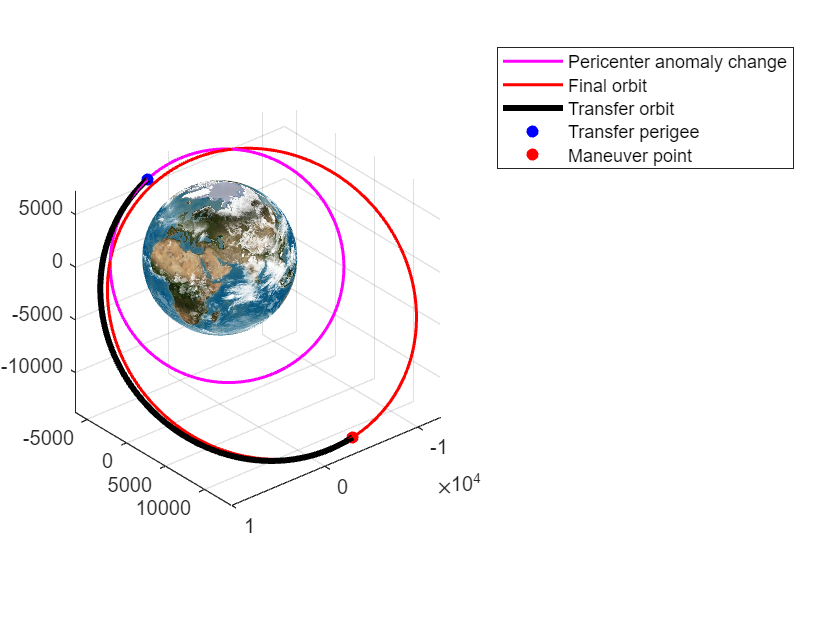

figure();
plotOrbit(a_anch, e_anch, i_anch, OM_anch, w_anch, 0, 2*pi, 0.01, mu, 'm');
hold on; axis equal; grid on;
plotOrbit(a_f, e_f, i_f, OM_f, w_f, 0, 2*pi, 0.01, mu, 'r');
p = plotOrbit(a_sec, e_sec, i_sec, OM_sec, w_sec, 0, theta_m, 0.01, mu, 'k');
set(p, 'LineWidth', 3);
scatter3(R_p_anch(1), R_p_anch(2), R_p_anch(3), 'blue', 'filled');
scatter3(R_f(1), R_f(2), R_f(3), 'red', 'filled');
view(140, 30);
earthPlot;
legend("Pericenter anomaly change", "Final orbit", "Transfer orbit", ...
    "Transfer perigee", "Maneuver point", 'Location', 'northeastoutside');

We can calculate the velocity variation needed:

v_p_anch = norm(V_p_anch);
v_p_sec = sqrt(mu/p_sec)*(1+e_sec);
v_m_sec = [sqrt(mu/p_sec)*(e_sec*sin(theta_m)) ...   % in {ir ith} system
           sqrt(mu/p_sec)*(1+e_sec*cos(theta_m))]; 
v_m_f = [0 sqrt(mu/(a_f*(1-e_f^2))*(1+e_f))];
dv_peri = v_p_sec - v_p_anch

dv_peri = 0.8021

dv_m = v_m_f - v_m_sec

dv_m =    -0.2163    3.2355


dv_tot_sec = abs(dv_peri) + norm(dv_m)

dv_tot_sec = 4.0448

As for the previous case, we can calculate the total time as the sum of the ones needed to reach every maneuver's point:

dt_anch_tras = CalcoloTempi(a_anch, e_anch, mu, theta_anch, 0) % [sec]

dt_anch_tras = 1.5463e+03

dt_ap_tras = CalcoloTempi(a_tras, e_tras, mu, 0, theta_m) % [sec]

dt_ap_tras = 7.3674e+03

dt_tras_f = CalcoloTempi(a_f, e_f, mu, theta_m, theta_f) % [sec]

dt_tras_f = 0

dt_anch_f = dt_anch_tras + dt_ap_tras + dt_tras_f % [sec]

dt_anch_f = 8.9137e+03

dt_anch_f/60^2 % [hr]

ans = 2.4760

The total time for the entire transfer is:

dt_tot_sec = dt_i_plch + dt_plch_anch + dt_anch_f % [sec]

dt_tot_sec = 1.7968e+04

dt_tot_sec/(60^2) % [hr]

ans = 4.9912

#### Considerations

If we group all the results we got we can see how the choice of the type of maneuver affects both $\Delta$v and $\Delta$t:

tab = table([dv_tot_pa; dv_tot_ap; dv_tot_sec], [dt_tot_pa; dt_tot_ap; dt_tot_sec]./(60^2), ...
    'RowNames',["Perigee-Apogee"; "Apogee-Perigee"; "Secant"], 'VariableNames',["Delta_v [Km/s]" "Delta_t [hr]"])

tab = 3×2 table
                      Delta_v [Km/s]    Delta_t [hr]
                      ______________    ____________

    Perigee-Apogee       0.89337           9.2231   
    Apogee-Perigee       0.92223           7.4772   
    Secant                4.0448           4.9912   


As we can see, the Perigee-Apogee maneuver is the best one if we need to have low $\Delta$v, but will take more time than the others; on the other hand, the Secant will need an higher $\Delta$v (over 300% more compared to the other two), but we'll let us have a smaller time to complete the transfer.

In the end however, the best maneuver in the contet of standard transfer is the Apogee-Perigee, as it requires only 3% more in terms of $\Delta$v, while needing almost 2 hours less than the Perigee-Apogee; compared to the secant it also grants us that the higher need for time (+50%) is balanced by the lower need for velocity variation (-300%), making this the optimal maneuver between the ones analyzed in the standard transfer.

## `NOTA``: MANCANO VARIAZIONI SU CAMBIO PIANO `

## `+ rivedere formattazione PDF`